## Table Properties

Import the spreadsheet `EPLteams.xlsx` as a table.

teaminfo = readtable('EPLteams.xlsx');

View the metadata associated with the table of English Premier League team information.

teaminfo.Properties

ans = struct with fields:
             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Team'  'Payroll_M__'  'Manager'  'ManagerHireDate'  'ManagerNationality'}
    VariableDescriptions: {''  'Original column heading: 'Payroll (M£)''  ''  'Original column heading: 'Manager Hire Date''  'Original column heading: 'Manager Nationality''}
           VariableUnits: {}
                RowNames: {}


Modify the table description to provide information on the data contained in the table.

## Indexing into Cell Arrays

Extract the managers’ names from the table `teaminfo`. Extract the fourth name. Note the size and class of the output.

mgmt = teaminfo.Manager;
m4 = mgmt(4)

m4 = cell
    'Guus Hiddink'


m4 = mgmt{4}

m4 = 'Guus Hiddink'

Modify the fourth element of the cell array.

%mgmt(4) = 'Antonio Conte'

Why doesn’t this work?

Try again, using cell indexing.

mgmt{4} = 'Antonio Conte'

mgmt = 20×1 cell array
    'Arsène Wenger'
    'Eric Black'
    'Eddie Howe'
    'Antonio Conte'
    'Alan Pardew'
    'David Unsworth'
    'Claudio Ranieri'
    'Jürgen Klopp'
    'Manuel Pellegrini'
    'Louis van Gaal'
    'Rafael Benítez'
    'Alex Neil'
    'Ronald Koeman'
    'Mark Hughes'
    'Sam Allardyce'
    'Francesco Guidolin'
    'Mauricio Pochettino'
    'Quique Sánchez Flores'
    'Tony Pulis'
    'Slaven Bilić'


Change the name of the payroll variable to remove extraneous characters.

teaminfo.Properties.VariableNames{2} = 'Payroll';

## Combining Tables

Load the file `EPLresults.mat`. Join the table containing season results with the table of team infomation.

load EPLresults
EPL = join(teaminfo,EPL,'Keys','Team')

EPL = 20×17 table
             Team             Payroll            Manager            ManagerHireDate    ManagerNationality    HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    Points    GD 
    ______________________    _______    _______________________    _______________    __________________    ________    _________    __________    ______    ______    ________    _________    __________    ______ 

## Representing Dates and Times

Extract the manager hire date. Note the size and type of the result.

mgrHireDate = EPL.ManagerHireDate

mgrHireDate = 20×1 datetime array
   10/1/1996 
   3/29/2016 
   10/12/2012
   12/19/2015
   1/2/2015  
   5/12/2016 
   7/13/2015 
   10/8/2015 
   6/14/2013 
   7/14/2014 
   3/11/2016 
   1/9/2015  
   6/16/2014 
   5/30/2013 
   10/9/2015 
   1/18/2016 
   5/27/2014 
   6/5/2015  
   1/1/2015  
   6/9/2015  


Sort the table by manager hire date.

byMHD = sortrows(EPL,'ManagerHireDate');
byMHD(:,{'Team','Manager','ManagerHireDate'})

ans = 20×3 table
             Team                     Manager            ManagerHireDate
    ______________________    _______________________    _______________

    'Arsenal'                 'Arsène Wenger'            10/1/1996      
    'Bournemouth'             'Eddie Howe'               10/12/2012     
    'Stoke City'              'Mark Hughes'              5/30/2013      
    'Manchester City'         'Manuel Pellegrini'        6/14/2013      
    'Tottenham Hotspur'       'Mauricio Pochettino'      5/27/2014      
    'Southampton'             'Ronald Koeman'            6/16/2014      
    'Manchester United'       'Louis van Gaal'           7/14/2014      
    'West Bromwich Albion'    'Tony Pulis'               1/1/2015       
    'Crystal Palace'          'Alan Pardew'              1/2/2015       
    'Norwich City'            'Alex Neil'                1/9/2015       
    

Create a datetime variable representing the season start date.

seasonStart = datetime(2015,8,8);

Calculate the tenure of each manager at the start of the season. Note the size and type of the result.

mgrTenure = seasonStart - mgrHireDate

mgrTenure = 20×1 duration array
   165240:00:00
    -5616:00:00
    24720:00:00
    -3192:00:00
     5232:00:00
    -6672:00:00
      624:00:00
    -1464:00:00
    18840:00:00
     9360:00:00
    -5184:00:00
     5064:00:00
    10032:00:00
    19200:00:00
    -1488:00:00
    -3912:00:00
    10512:00:00
     1536:00:00
     5256:00:00
     1440:00:00


Calculate the tenure in days. Note the size and type of the result.

mgrTenureD = days(mgrTenure)

mgrTenureD =         6885
        -234
        1030
        -133
         218
        -278
          26
         -61
         785
         390


## Displaying and Plotting Dates

Plot the each team’s number of home wins by their manager’s hire date.

plot(EPL.ManagerHireDate,EPL.HomeWins,'*')

Adjust the x-axis limits to ignore the outlier.

t1 = datetime(2012,7,1);
t2 = datetime(2016,7,1);
xlim([t1,t2])

Add a vertical line at the season start date. Do managers hired before or after the season start appear to have more home wins?

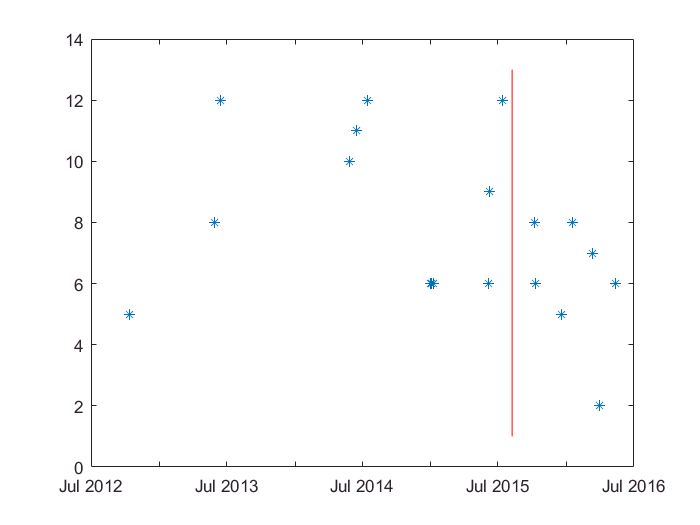

hold on
plot([seasonStart seasonStart],[1 13],'r')
hold off

In which months are managers commonly hired?

hireMonth = month(EPL.ManagerHireDate);
histogram(hireMonth)

Modify the x-axis labels.

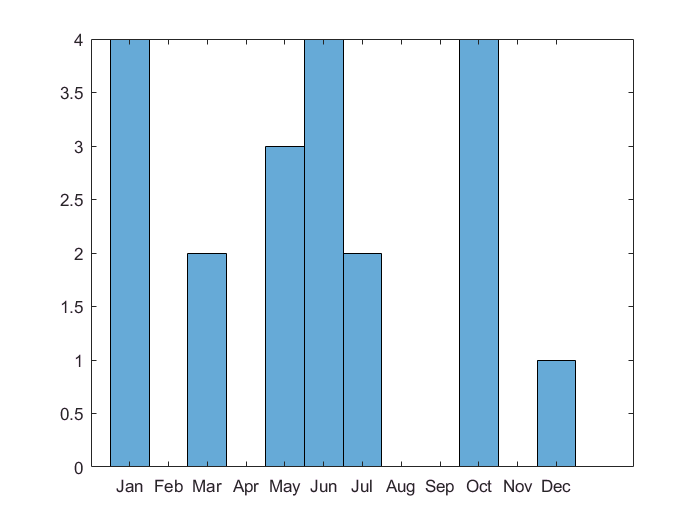

t = datetime(2016,1:12,1);
mths = month(t,'shortname');
xticks(1:12)
xticklabels(mths)

## Representing Discrete Categories

Try to investigate the number of managers from England. Why doesn’t this work?

%nnz(EPL.ManagerNationality == 'England')
nat = EPL.ManagerNationality;
whos nat

  Name       Size            Bytes  Class    Attributes

  nat       20x1              2522  cell               



Convert the countries to a categorical array.

EPL.ManagerNationality = categorical(EPL.ManagerNationality);
ctry = EPL.ManagerNationality;
whos ctry

  Name       Size            Bytes  Class          Attributes

  ctry      20x1              1404  categorical              



Try again to find the number of managers from England. What set of countries are represented by the managers? How many managers are from each country?

nnz(ctry == 'England')

ans = 4

cats = categories(ctry)

cats = 11×1 cell array
    'Argentina'
    'Chile'
    'Croatia'
    'England'
    'France'
    'Germany'
    'Italy'
    'Netherlands'
    'Scotland'
    'Spain'
    'Wales'


summary(ctry)

     Argentina        1 
     Chile            1 
     Croatia          1 
     England          4 
     France           1 
     Germany          1 
     Italy            2 
     Netherlands      3 
     Scotland         2 
     Spain            2 
     Wales            2 


How many managers are from the UK?

catsUK = {'England','Scotland','Wales'};
natUK = mergecats(ctry,catsUK,'UK');
nnz(natUK == 'UK')

ans = 8